% 1. Cargar las variables de entrenamiento
load('pell.mat');  

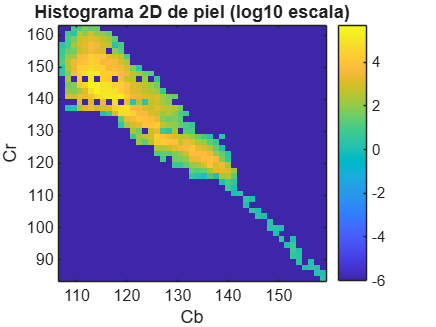

%-------------------------------------------
%algo1: Crear histograma modelo de píxeles de piel usando las máscaras manuales
%--------------------------------------------
% Extraer, para cada imagen, los valores de Cb y Cr sólo en los píxeles marcados como piel de las máscaras (BW)
imgNums = 1:60; % Tenemos 60 máscaras en total

% imgFiles contendrá nombres de archivos de imagen formateados
% %maskFiles contendrá nombres de archivos de máscara, como BW1, BW2, etc., basados en los números en imgNums
imgFiles = cellfun(@(n) sprintf('inputImage%d', n), num2cell(imgNums), 'UniformOutput', false);
maskFiles = cellfun(@(n) sprintf('BW%d', n), num2cell(imgNums), 'UniformOutput', false);

% Acumular todos los valores en los vectores all_Cb y all_Cr
% Convierte cada imagen a YCbCr y extrae los canales Cb (azul-croma) y Cr (rojo-croma)
% Sólo guarda los valores de los píxeles donde BW==1 (las zonas marcadas como piel manualmente)
all_Cb = [];
all_Cr = [];

for k = 1:length(imgFiles)
    img = eval(imgFiles{k});   % Carga la imagen RGB
    mask = eval(maskFiles{k}); % Su máscara de piel (BW)
    
    imgYCbCr = rgb2ycbcr(img);
    cb = imgYCbCr(:,:,2);
    cr = imgYCbCr(:,:,3);
    cb_skin = cb(mask==1);     % Solo donde hay piel
    cr_skin = cr(mask==1);
    all_Cb = [all_Cb; cb_skin(:)];
    all_Cr = [all_Cr; cr_skin(:)];
end

%Construir el histograma modelo 2D

% Lo ideal es que la mayoría de bins del histograma tengan algo de frecuencia en las imágenes de piel

% Calcular edges óptimos
Cb_min = double(min(all_Cb));
Cb_max = double(max(all_Cb));
Cr_min = double(min(all_Cr));
Cr_max = double(max(all_Cr));

% Si se baja demasiado los bins, puedes empezar a etiquetar "no piel" comopiel (más falsos positivos)
nBins = 45; % % Número de bins para el histograma
Cb_edges = linspace(Cb_min, Cb_max, nBins + 1);
Cr_edges = linspace(Cr_min, Cr_max, nBins + 1);


% Construir el histograma sólo con los valores relevantes
hist_2d = histcounts2(all_Cb, all_Cr, Cb_edges, Cr_edges);

save('histograma_modelo.mat', 'hist_2d', 'Cb_edges', 'Cr_edges');

% Visualizar el histograma 2D

figure;
imagesc(Cb_edges(1:end-1), Cr_edges(1:end-1), log10(hist_2d'+1e-6));
set(gca,'YDir','normal');
xlabel('Cb'); ylabel('Cr'); title('Histograma 2D de piel (log10 escala)');
colorbar;

% Comprobación y optimización de numero de bins
% hay que buscar un equilibrio entre resolución y cantidad real de muestras por bin

% Si los bins son ENORMES, habran segmentaciones MUY groseras (muchos falsos positivos)
% Si los bins son DEMASIADO pequeños, acabaran con "agujeros" (falsos negativos)

nnz(hist_2d) % Número de bins no nulos

ans = 365

pctNulos = 100*nnz(hist_2d)/numel(hist_2d);
fprintf("Porcentaje de bins no nulos: %.2f%%\n", pctNulos);

Porcentaje de bins no nulos: 18.02%


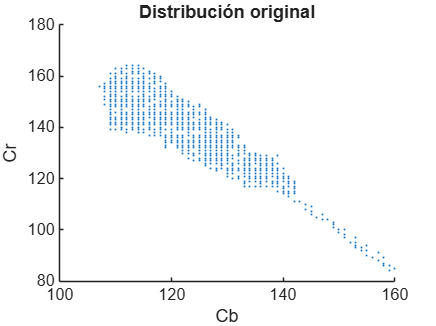


figure; scatter(all_Cb, all_Cr, 1, '.'); xlabel('Cb'); ylabel('Cr'); title('Distribución original');

%-----------------------------------------------------
% algo2: Detección de piel usando el histograma modelo
%-----------------------------------------------------
function BW_piel = algo2(imagenRGB, hist_2d, Cb_edges, Cr_edges, umbral)
    % imagenRGB: imagen de entrada (uint8, 3 canales)
    % hist_2d, Cb_edges, Cr_edges: tu modelo de piel (de algo1)
    % umbral: frecuencia mínima en el histograma para considerar piel

    imgYCbCr = rgb2ycbcr(imagenRGB);
    cb = double(imgYCbCr(:,:,2));
    cr = double(imgYCbCr(:,:,3));

    % A qué bin corresponde cada píxel
    bin_Cb = discretize(cb, Cb_edges); % Mapa de índices de Cb (por píxel)
    bin_Cr = discretize(cr, Cr_edges); % Mapa de índices de Cr (por píxel)

    % Sólo consideramos los índices válidos
    valid_mask = ~isnan(bin_Cb) & ~isnan(bin_Cr) & ...
                 bin_Cb > 0 & bin_Cr > 0 & ...
                 bin_Cb <= size(hist_2d,1) & bin_Cr <= size(hist_2d,2);

    % Índices lineales en el histograma
    ind = sub2ind(size(hist_2d), bin_Cb(valid_mask), bin_Cr(valid_mask));

    % Inicializa máscara
    BW_piel = false(size(cb));


    % Clasifica como piel si frecuencia en el histograma es mayor que el umbral
    BW_piel(valid_mask) = hist_2d(ind) > umbral;
  
end


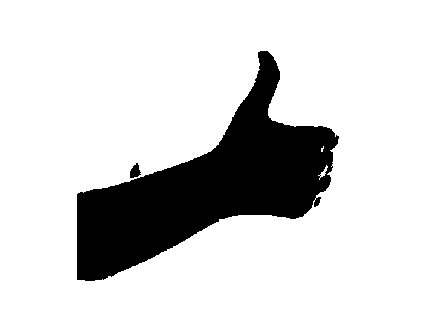

% Script principal (ejemplo de una sola imagen)
umbral = 26000;

load('modelo_histograma.mat');         % Para tener hist_2d, Cb_edges, Cr_edges
img = imread('Images/1_P_hgr1_id02_2.jpg');

                        
BW_piel = algo2(img, hist_2d, Cb_edges, Cr_edges, umbral);
imshow(~BW5) %Mascara hecha manualmente 

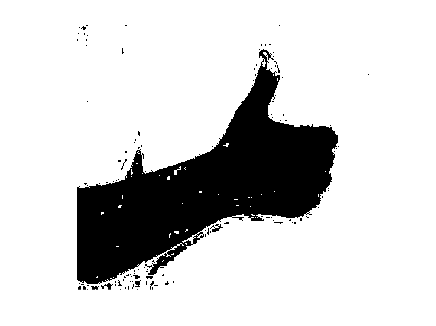

imshow(~BW_piel) % Para ver la máscara resultante

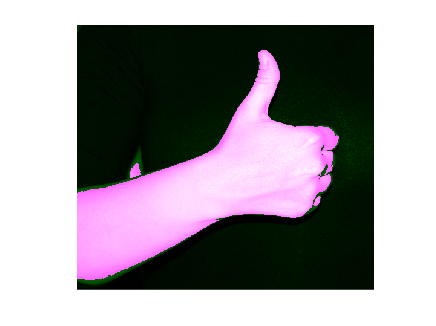

imshowpair(inputImage5, BW5); % Comparación de la mascara manual con la original

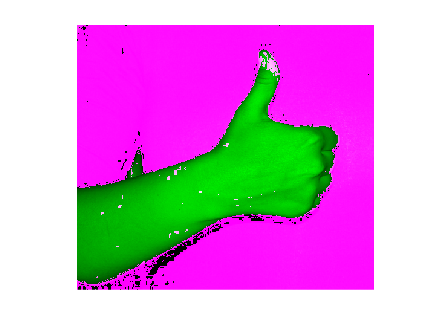

imshowpair(inputImage5, ~BW_piel); % Comparación de la mascara resultante con la original

% algo3: procesamiento de todas las imagines y guardado de las máscaras

imageDir = 'Images';        % Directorio de imágenes a segmentar
maskDir  = 'Masks';         % Carpeta donde guardarás las máscaras segmentadas
if ~exist(maskDir, 'dir')
    mkdir(maskDir);
end

load('histograma_modelo.mat'); % hist_2d, Cb_edges, Cr_edges

%counts = hist_2d(hist_2d > 0);
umbral = 26000;
imageFiles = dir(fullfile(imageDir, '*.jpg'));

for k = 1:length(imageFiles)
    img = imread(fullfile(imageDir, imageFiles(k).name));
    BW_piel = algo2(img, hist_2d, Cb_edges, Cr_edges, umbral);
    BW_piel = ~BW_piel;
    [~, baseName, ~] = fileparts(imageFiles(k).name);
    maskName = [baseName '.bmp'];
    imwrite(BW_piel, fullfile(maskDir, maskName));
   
end


disp('¡Todas las segmentaciones están guardadas en la carpeta Masks!');

¡Todas las segmentaciones están guardadas en la carpeta Masks!


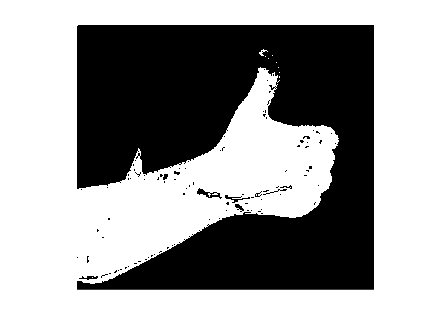

% Comprobacion de una sola mascara
mask = imread('Masks/1_P_hgr1_id02_2.bmp'); 
ideal = imread('Masks-Ideal/1_P_hgr1_id02_2.bmp');
imshow(~mask);

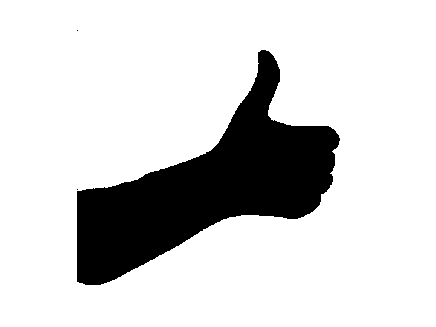

imshow(ideal);

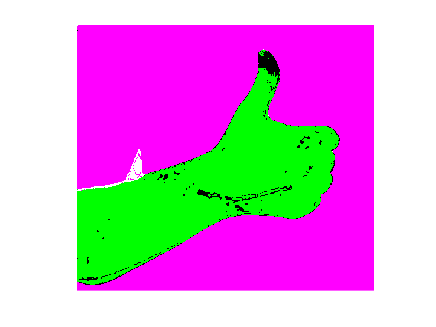

imshowpair(~mask, ideal)

%---------------------------------
% algo4:
%----------------------------------
maskDir = 'Masks';
idealDir = 'Masks-Ideal';

maskFiles = dir(fullfile(maskDir, '*.bmp'));
F_scores = zeros(length(maskFiles),1);
precision_vals = zeros(length(maskFiles),1);
recall_vals = zeros(length(maskFiles),1);

%{
% Haz loop por nombres, no por orden:
for k = 1:length(maskFiles)
    mask_name = maskFiles(k).name;
    mask_path = fullfile(maskDir, mask_name);
    ideal_path = fullfile(idealDir, mask_name);
    if ~exist(ideal_path, 'file')
        warning('Saltando %s: sin ideal correspondiente', mask_name);
        continue
    end
    
    mask = imread(fullfile(maskDir, maskFiles(k).name));
    ideal = imread(fullfile(idealDir, maskFiles(k).name));
    mask = mask > 0;
    ideal = ideal > 0;

   %mask = ~mask;    % <--- INVERTIR AQUÍ!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!


    if ~isequal(size(mask), size(ideal))
        warning('Error: Las máscaras no tienen la misma dimensión en %s', mask_name);
        continue
    end

    TP = sum(mask(:) & ideal(:));
    FP = sum(mask(:) & ~ideal(:));
    FN = sum(~mask(:) & ideal(:));

    if (TP+FP)==0
        precision = NaN;
    else
        precision = TP / (TP + FP);
    end

    if (TP+FN)==0
        recall = NaN;
    else
        recall = TP / (TP + FN);
    end

    if isnan(precision) || isnan(recall) || (precision+recall)==0
        F = NaN;
    else
        F = 2 * precision * recall / (precision + recall);
    end

    precision_vals(k) = precision;
    recall_vals(k) = recall;
    F_scores(k) = F;
end



fprintf('F-score medio: %.3f\n', nanmean(F_scores));
fprintf('Precisión media: %.3f\n', nanmean(precision_vals));
fprintf('Recall media: %.3f\n', nanmean(recall_vals));

% Visualizar grafica resultante
% Definim els eixos de Recall i Precision
figure;
hold on;
recall = linspace(0, 1, 100);
precision = linspace(0, 1, 100);

plot(recall_vals, precision_vals, 'bo');

grid on;
xlim([0 1]);
ylim([0 1]);

% Añadir los números a cada punto, desplazados a la derecha
for k = 1:length(recall_vals)
    if ~isnan(recall_vals(k)) && ~isnan(precision_vals(k))
        text(recall_vals(k)+0.015, precision_vals(k), num2str(k), ...
            'FontSize',8, 'HorizontalAlignment','left', 'VerticalAlignment','middle', 'Color','b');
    end
end

% Creem una malla
[R, P] = meshgrid(recall, precision);

% Calculem el F-score per cada punt
F = 2 * (P .* R) ./ (P + R);
F(isnan(F)) = 0; % per evitar NaN quan P+R=0

% Dibuixem les línies de nivell de F-score

contour(R, P, F, 0:0.1:1);
xlabel('Recall');
ylabel('Precision');
title('Precision-Recall');
%}

% Inicializar vectores para evitar problemas con índices
precision_vals = NaN(1, length(maskFiles));
recall_vals = NaN(1, length(maskFiles));
F_scores = NaN(1, length(maskFiles));

% Haz loop por nombres, no por orden:
for k = 1:length(maskFiles)
    mask_name = maskFiles(k).name;
    mask_path = fullfile(maskDir, mask_name);
    ideal_path = fullfile(idealDir, mask_name);
    
    if ~exist(ideal_path, 'file')
        warning('Saltando %s: sin ideal correspondiente', mask_name);
        % Asignar NaN para mantener alineacion de índices
        precision_vals(k) = NaN;
        recall_vals(k) = NaN;
        F_scores(k) = NaN;
        continue
    end
    
    mask = imread(mask_path);
    ideal = imread(ideal_path);
    
    % Comprobar que son imágenes binarias 2D, no RGB u otro formato
    if ndims(mask) ~= 2 || ndims(ideal) ~= 2
        warning('Saltando %s: imágenes no binarias o no 2D', mask_name);
        precision_vals(k) = NaN;
        recall_vals(k) = NaN;
        F_scores(k) = NaN;
        continue
    end
    
    mask = mask > 0;
    ideal = ideal > 0;
    
    %mask = ~mask; % <--- INVERTIR AQUÍ!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!

    if ~isequal(size(mask), size(ideal))
        warning('Error: Las máscaras no tienen la misma dimensión en %s', mask_name);
        precision_vals(k) = NaN;
        recall_vals(k) = NaN;
        F_scores(k) = NaN;
        continue
    end

    TP = sum(mask(:) & ideal(:));
    FP = sum(mask(:) & ~ideal(:));
    FN = sum(~mask(:) & ideal(:));
    
    if (TP + FP) == 0
        precision = NaN;
    else
        precision = TP / (TP + FP);
    end
    
    if (TP + FN) == 0
        recall = NaN;
    else
        recall = TP / (TP + FN);
    end
    
    if isnan(precision) || isnan(recall) || (precision + recall) == 0
        F = NaN;
    else
        F = 2 * precision * recall / (precision + recall);
    end
    
    precision_vals(k) = precision;
    recall_vals(k) = recall;
    F_scores(k) = F;
end

fprintf('F-score medio: %.3f\n', nanmean(F_scores));

F-score medio: 0.924


fprintf('Precisión media: %.3f\n', nanmean(precision_vals));

Precisión media: 0.910


fprintf('Recall media: %.3f\n', nanmean(recall_vals));

Recall media: 0.943


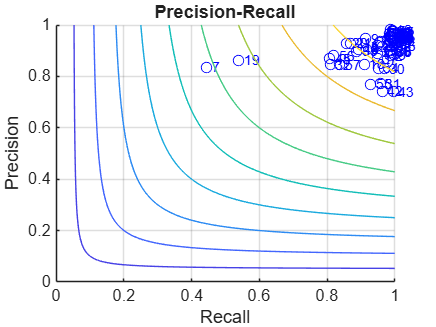


% Visualizar grafica resultante
% Definimos los ejes de Recall y Precision
figure;
hold on;
recall = linspace(0, 1, 100);
precision = linspace(0, 1, 100);

plot(recall_vals, precision_vals, 'bo');

grid on;
xlim([0 1]);
ylim([0 1]);

% Añadir los números a cada punto, desplazados a la derecha
for k = 1:length(recall_vals)
    if ~isnan(recall_vals(k)) && ~isnan(precision_vals(k))
        text(recall_vals(k)+0.015, precision_vals(k), num2str(k), ...
             'FontSize',8, 'HorizontalAlignment','left', 'VerticalAlignment','middle', 'Color','b');
    end
end

% Creamos una malla
[R, P] = meshgrid(recall, precision);

% Calculamos el F-score para cada punto
F = 2 * (P .* R) ./ (P + R);
F(isnan(F)) = 0; % evitar NaN cuando P+R=0

% Dibujamos las líneas de nivel de F-score
contour(R, P, F, 0:0.1:1);
xlabel('Recall');
ylabel('Precision');
title('Precision-Recall');